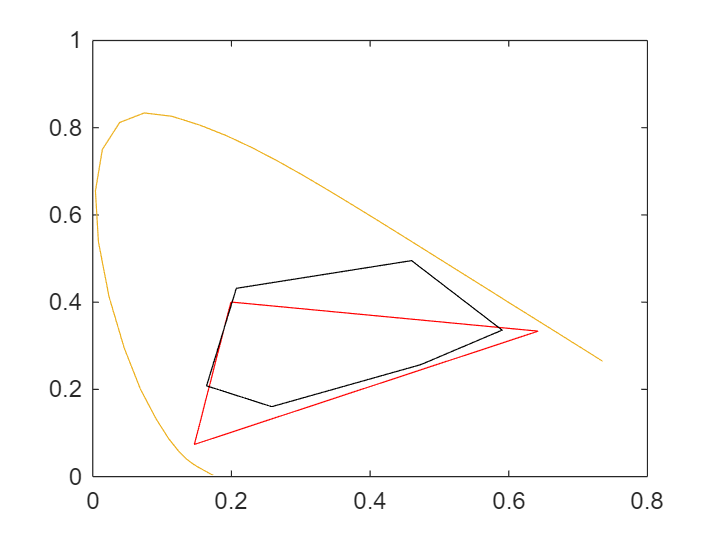

%1
clear
load("Dell.mat")
load("Inkjet.mat")

hold off
plot_chrom(XYZdell,"r") %r, red
plot_chrom(XYZinkjet,"k")%k is black in cmyk

Inkjet covers a somewhat larger area in general but misses some of the reds and blues that dell covers, mainly blue though.

%2.1.1
clear
%Load with imread and immediately convert to double
grayPeppers=im2double(imread("peppers_gray.tif"));
save("grayPeppers","grayPeppers")

%Img resizing
nearestPeppers=imresize(imresize(grayPeppers,0.25,"nearest"),4,"nearest");
bilinearPeppers=imresize(imresize(grayPeppers,0.25,"bilinear"),4,"bilinear");
bicubicPeppers=imresize(imresize(grayPeppers,0.25,"bicubic"),4,"bicubic");

%SNR Calc
"SNR"

ans = "SNR"

snr(grayPeppers,grayPeppers-nearestPeppers)

ans = 17.0956

mysnr(grayPeppers,grayPeppers-nearestPeppers)

ans = 17.0956


snr(grayPeppers,grayPeppers-bilinearPeppers)

ans = 18.8922

mysnr(grayPeppers,grayPeppers-bilinearPeppers)

ans = 18.8922


snr(grayPeppers,grayPeppers-bicubicPeppers)

ans = 19.8538

mysnr(grayPeppers,grayPeppers-bicubicPeppers)

ans = 19.8538


%MSE Calc
"MSE"

ans = "MSE"

immse(grayPeppers,grayPeppers-nearestPeppers)

ans = 0.2218

immse(grayPeppers,grayPeppers-bilinearPeppers)

ans = 0.2147

immse(grayPeppers,grayPeppers-bicubicPeppers)

ans = 0.2172

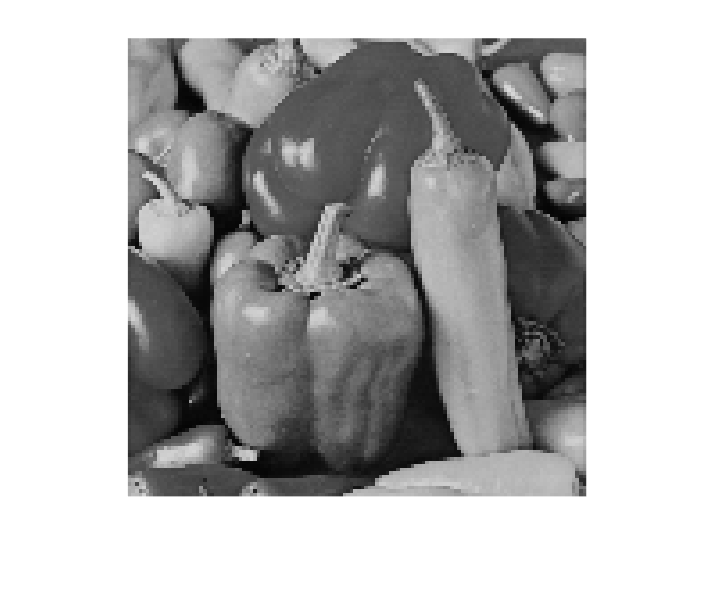


%Visual comparison
imshow(nearestPeppers)

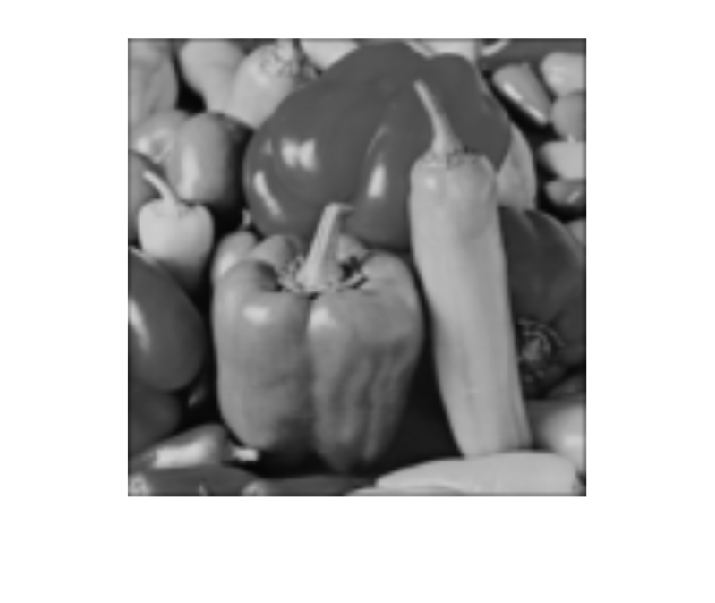

imshow(bilinearPeppers)

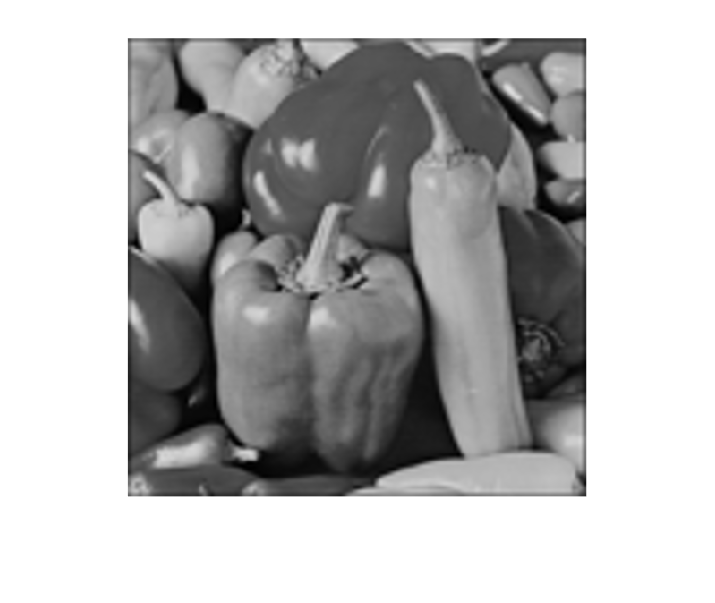

imshow(bicubicPeppers)

Bicubic is visually the best representation.

MSE thinks they're all about the same, but SNR (which is better the higher) would argue it's Bicubic.

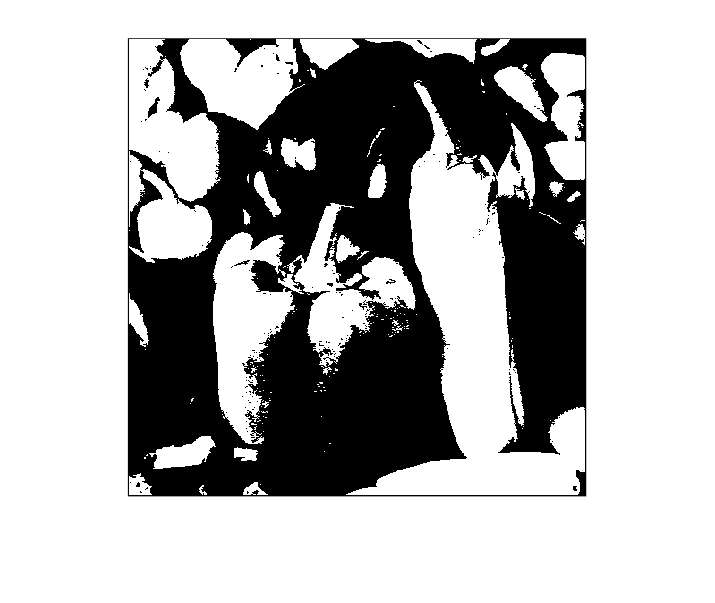

%2.1.2
%imThresh=double(grayPeppers>=0.65);
imThresh=double(grayPeppers>=0.5);
save("imThresh","imThresh");
imshow(imThresh)

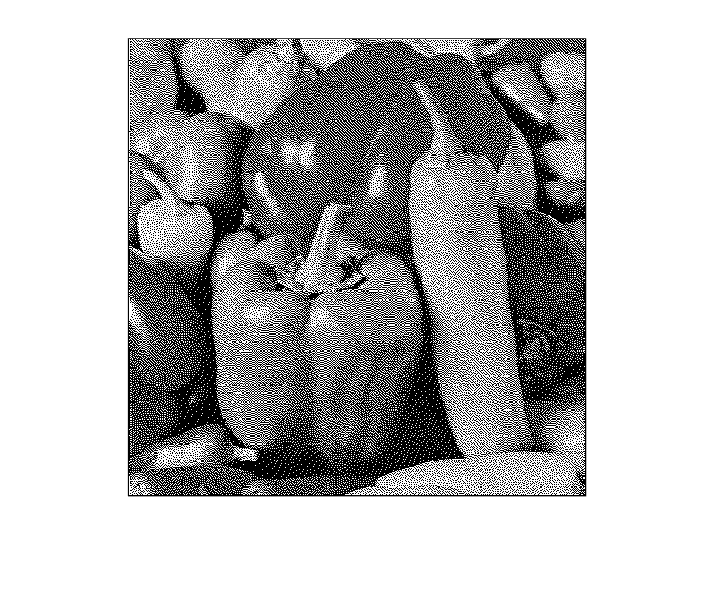


imDither=double(dither(grayPeppers));
save("imDither","imDither");
imshow(imDither)


snr(grayPeppers,grayPeppers-imDither)

ans = 0.4112

snr(grayPeppers,grayPeppers-imThresh)

ans = 2.9721

immse(grayPeppers,grayPeppers-imDither)

ans = 0.4216

immse(grayPeppers,grayPeppers-imThresh)

ans = 0.4006


snr(grayPeppers,grayPeppers-imThresh)

ans = 2.9721

snr(grayPeppers,grayPeppers-imDither)

ans = 0.4112

According to mse imdither is about the same as imthresh.

SNR identifies this imdither as a better sowith a higher score.

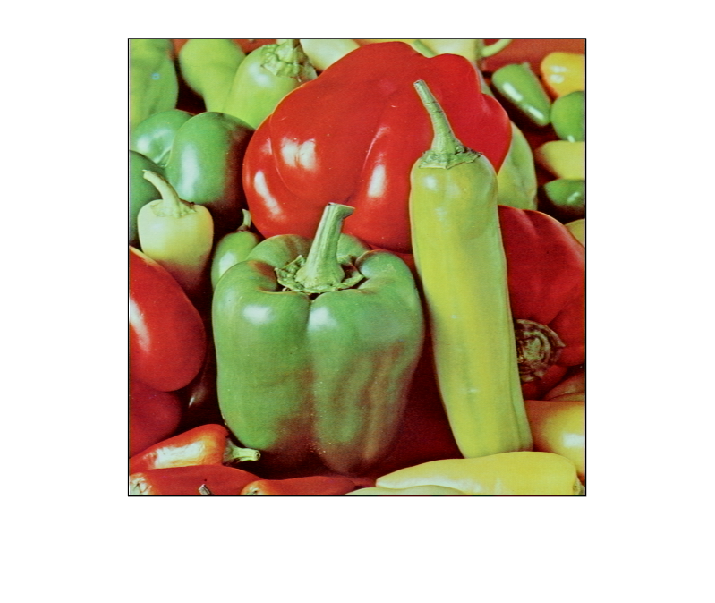

%2.2
clear
%Load RGB image
colorPeppers=im2double(imread("peppers_color.tif"));
imshow(colorPeppers)

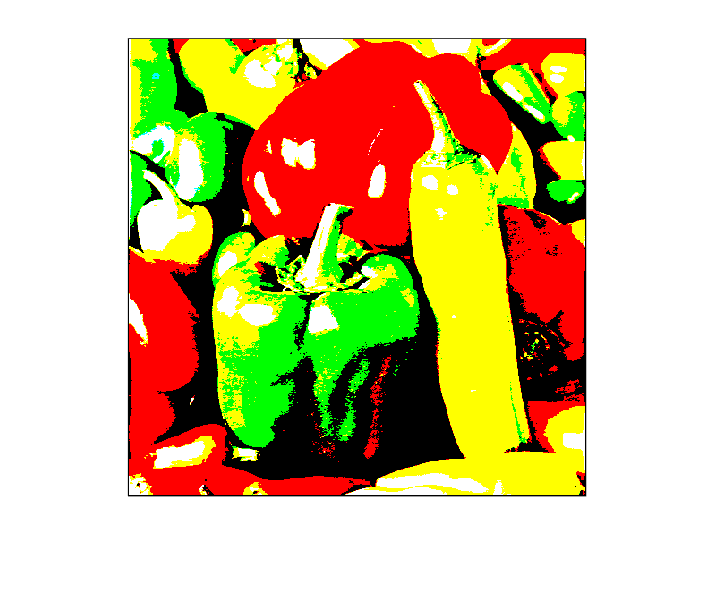


%Half-tone channels by thresholding
htTHColorPeppers=cat(3,double(colorPeppers(:,:,1)>=0.5),double(colorPeppers(:,:,2)>=0.5),double(colorPeppers(:,:,3)>=0.5));
imshow(htTHColorPeppers)

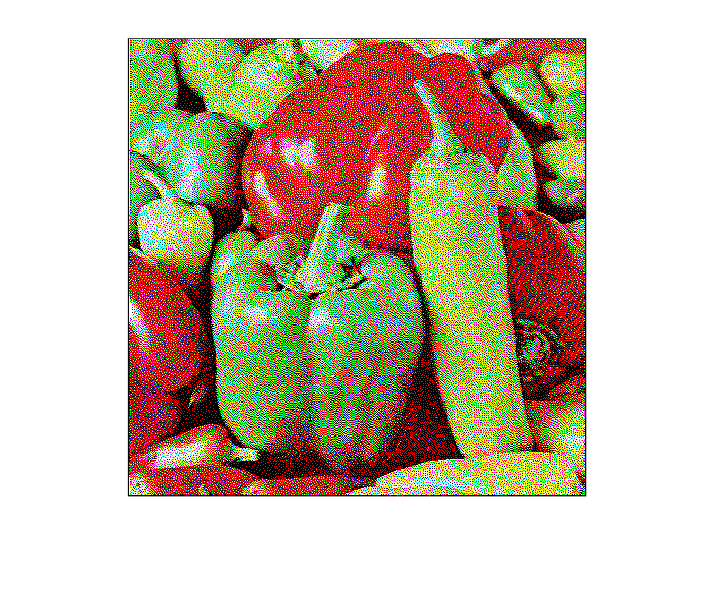


%Dither half-toning
htDTColorPeppers=cat(3,double(dither(colorPeppers(:,:,1))),double(dither(colorPeppers(:,:,2))),double(dither(colorPeppers(:,:,3))));
imshow(htDTColorPeppers)


%Convert to Lab
labPeppers=rgb2lab(colorPeppers);
labhtTHPeppers=rgb2lab(htTHColorPeppers);
labhtDTPeppers=rgb2lab(htDTColorPeppers);
immse(labPeppers,labPeppers-labhtDTPeppers)

ans = 4.1064e+03

immse(labPeppers,labPeppers-labhtTHPeppers)

ans = 4.3088e+03


snr(labPeppers,labPeppers-labhtDTPeppers)

ans = -0.7229

snr(labPeppers,labPeppers-labhtTHPeppers)

ans = 2.9889

MSE puts the thresholded image as WILDLY of, sure it's not super accurate but it's definately not THAT bad. SNR puts them as somewhat equal, with dither being slightly better which i would agree on.

%3.1
clear
load("imDither.mat")
load("imThresh.mat")
load("grayPeppers.mat")

ditherNoise=grayPeppers-imDither;
threshNoise=grayPeppers-imThresh;
imshow(imDither)

snr_filter(imDither,ditherNoise)

ans = 13.5280

imshow(imThresh)

snr_filter(imThresh,threshNoise)

ans = 5.8391

If higher snr is better then it would correctly identify now that the dither representations is better.

%3.2
clear
colorPeppers=im2double(imread("peppers_color.tif"));
labPeppers=rgb2lab(rgb_filter(colorPeppers));

%Remake the half-toning but now apply filter before Lab
%Half-tone channels by thresholding
htTHColorPeppers=cat(3,double(colorPeppers(:,:,1)>=0.5),double(colorPeppers(:,:,2)>=0.5),double(colorPeppers(:,:,3)>=0.5));
imshow(htTHColorPeppers)


%Dither half-toning
htDTColorPeppers=cat(3,double(dither(colorPeppers(:,:,1))),double(dither(colorPeppers(:,:,2))),double(dither(colorPeppers(:,:,3))));
imshow(htDTColorPeppers)


%Convert to Lab & apply filter
labhtTHPeppers=rgb2lab(rgb_filter(htTHColorPeppers));
labhtDTPeppers=rgb2lab(rgb_filter(htDTColorPeppers));
"Dither"

ans = "Dither"

immse(labhtDTPeppers,labPeppers)

ans = 176.7340

"Threshold"

ans = "Threshold"

immse(labhtTHPeppers,labPeppers)

ans = 865.1154

MSE still thinks dither is the best representation but it likes it far less than previously.

%4.1 S-CIELab
clear

%Prep basics for S-CIELab
colorPeppers=im2double(imread("peppers_color.tif"));
xyzPeppers=rgb2xyz(colorPeppers);
CIED65=[95.05, 100, 108.9];
d=15.7;         % =40cm
ppi=267;        % pixels per inch for Surface Pro 6
sampPerDegree=ppi*d*tan(pi/180);

%Img resizing
nearestPeppers=rgb2xyz(imresize(imresize(colorPeppers,0.25,"nearest"),4,"nearest"));
bilinearPeppers=rgb2xyz(imresize(imresize(colorPeppers,0.25,"bilinear"),4,"bilinear"));
bicubicPeppers=rgb2xyz(imresize(imresize(colorPeppers,0.25,"bicubic"),4,"bicubic"));

%Compute scielab
scieNearest=scielab(sampPerDegree,xyzPeppers,nearestPeppers,CIED65,'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


scieBilinear=scielab(sampPerDegree,xyzPeppers,bilinearPeppers,CIED65,'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


scieBicubic=scielab(sampPerDegree,xyzPeppers,bicubicPeppers,CIED65,'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


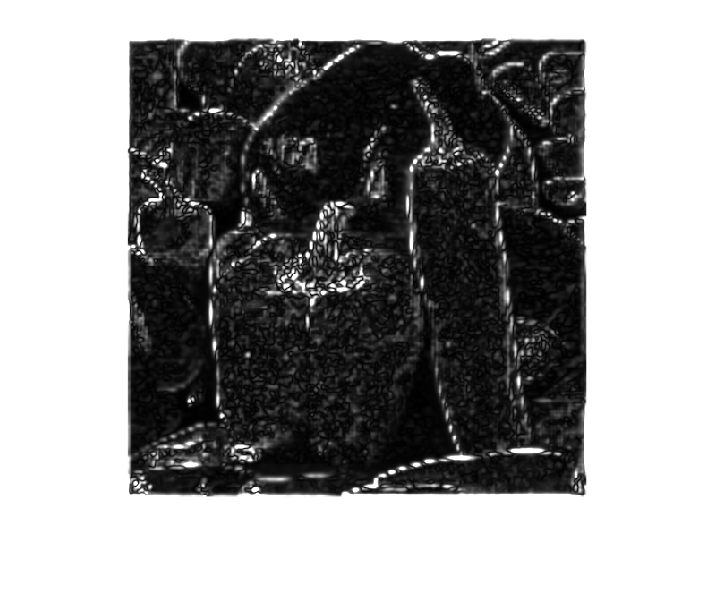


%Get the means
diffNearest=mean(mean(scieNearest));
diffBilinear=mean(mean(scieBilinear));
diffBicubic=mean(mean(scieBicubic));

%Scielab images
imshow(scieNearest)

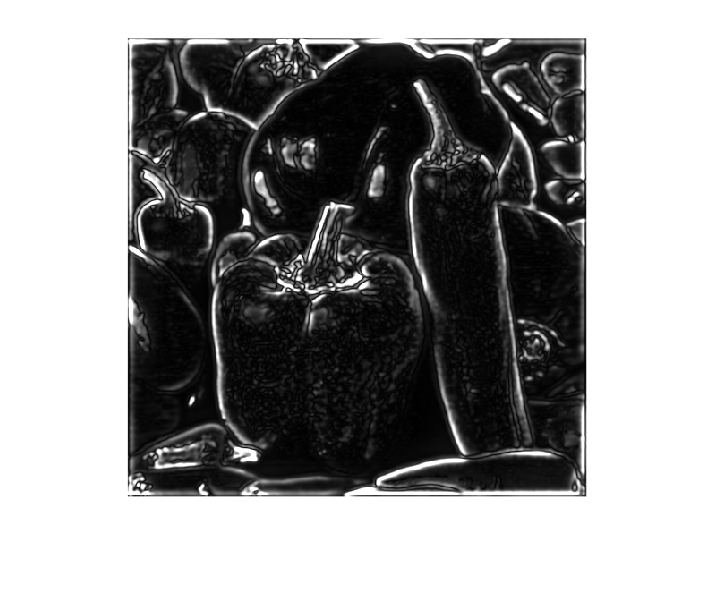

imshow(scieBilinear)

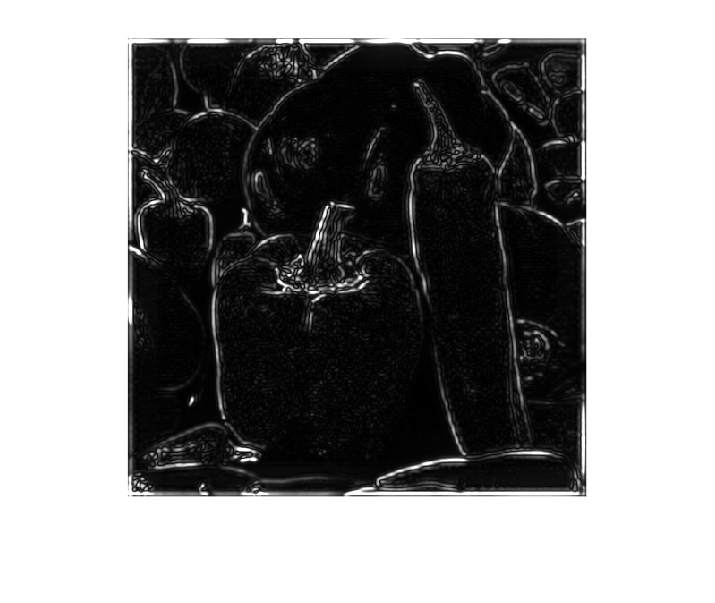

imshow(scieBicubic)

Bicubic has the lowest mean difference, which affirms the viewable assumption, that bicubic is the better method. When viewing the differences of the images, certain aspects are clearly visible, bilinear which was a blurry result has a lot of contours in the differences image, while bicubic have som minor highfrequency details missing.

%4.2
%Clear and do basic prep
clear
load("colorhalftones.mat")
d=15.7;         % =40cm
ppi=267;        % pixels per inch for Surface Pro 6
sampPerDegree=ppi*d*tan(pi/180);

%Convert all halftone patches to xyz
c1XYZ=rgb2xyz(c1);
c2XYZ=rgb2xyz(c2);
c3XYZ=rgb2xyz(c3);
c4XYZ=rgb2xyz(c4);
c5XYZ=rgb2xyz(c5);

%Use S-CIELab in the secondary method
scieC1=scielab(sampPerDegree,c1XYZ);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scieC2=scielab(sampPerDegree,c2XYZ);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scieC3=scielab(sampPerDegree,c3XYZ);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scieC4=scielab(sampPerDegree,c4XYZ);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


scieC5=scielab(sampPerDegree,c5XYZ);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


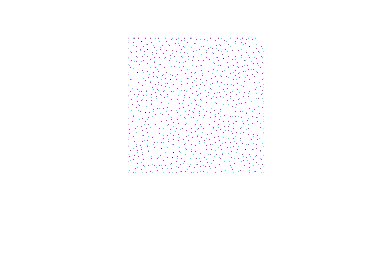


%Show c1 and c2 comparison
imshow(c1)

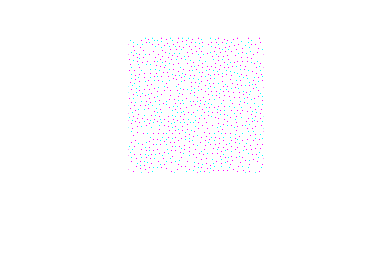

imshow(c2)

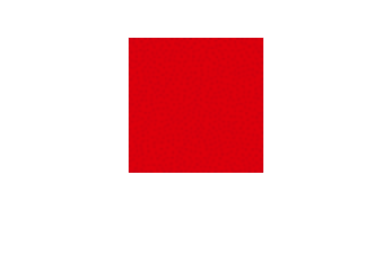

imshow(scieC1)

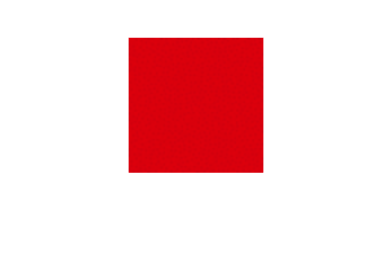

imshow(scieC2)

Both are just red? Red and kinda grainy, very hard to see though. They seem almost identical, and scielab seems to think so aswell.

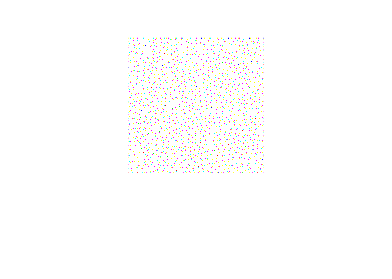

imshow(c3)

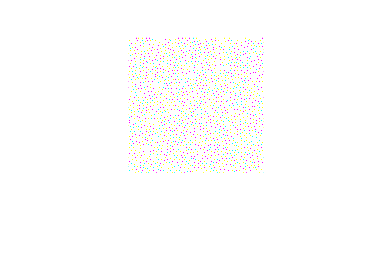

imshow(c4)

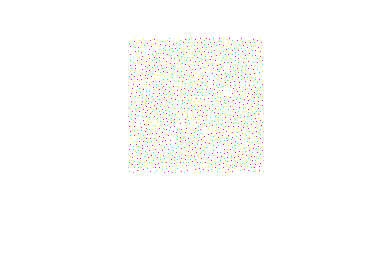

imshow(c5)

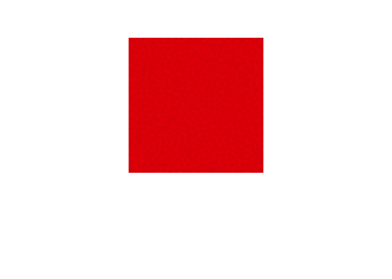

imshow(scieC3)

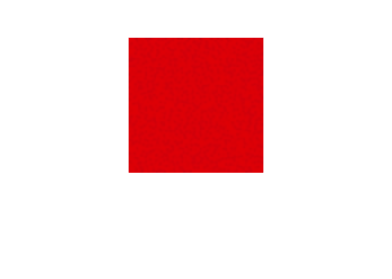

imshow(scieC4)

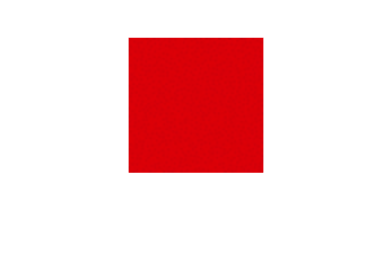

imshow(scieC5)

They all again are red and a little red, they seem identical, scieC4 is far grainier.

%5 - SSIM
clear

im_ssim=im2double(imread("peppers_gray.tif"));
sizeOfImage=size(im_ssim,1);
a1Distortion=zeros(sizeOfImage);
a2Distortion=a1Distortion;

%Distort a1Distortion
for i=1:sizeOfImage
    if(mod(i,2)==0)
        a1Distortion(i,:)=im_ssim(i,:)+0.1;
    else
        a1Distortion(i,:)=im_ssim(i,:)-0.1;
    end
end

%Distort a2Distortion
for i=1:sizeOfImage
    if(i>(sizeOfImage/2))
        a2Distortion(i,:)=im_ssim(i,:)+0.1;
    else
        a2Distortion(i,:)=im_ssim(i,:)-0.1;
    end
end

snr(im_ssim,im_ssim-a1Distortion)

ans = 13.4303

snr(im_ssim,im_ssim-a2Distortion)

ans = 13.4303

%Identical SNR

